# ENGR 845 Mini Project Assignment: Human Activity Classification Using Smartphone Data - Aaron Singh 

The purpose of this assignment is for the students to gain hands-on experience with the concepts taught in the class including human data processing, feature engineering, pattern classification, and parameter tuning.

References: 

- Canvas -> Mini Project -> Reference Materials -> Collect Accelerometer Data from Smartphone (For Use in Matlab)

- Canvas -> Mini Project -> Reference Materials -> Adding Machine Learning to Signal Processing Application

- Canvas -> Mini Project -> Reference Materials -> EMG PR code 2.0 

- Canvas -> Weekly Lecture Slides 

- Professor Yuriah

Please read the instructions below and complete the required fields marked with an *. 

## Project Organization 

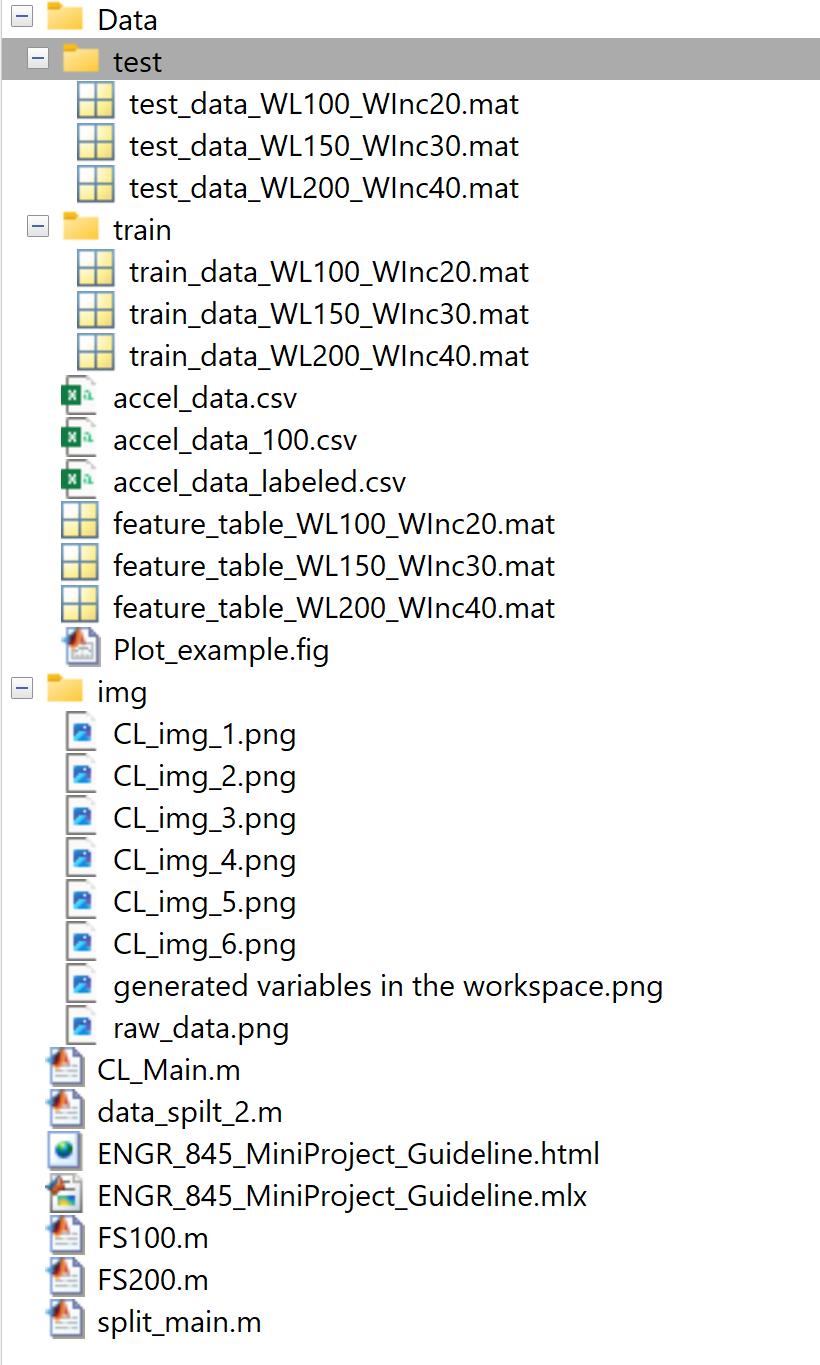

## **Img folder has all the given screenshots for the required MINI Project.**

## Data Collection

In this assignment, 3-axis acceleration data from an ***Android 13 Samsung A51 5G** (*please complete with the device OS and model*) for **at least three** different classes of human activities (e.g. sitting, **standing**, **walking**, **running**, **dancing**, riding bicycle, jumping, falling, etc.) are collected from yourself. *These motions are (*please complete*)

- **Walking**

- **Running**

- **Dancing**

- **Standing**

*Please describe how the data are collected, including (*please put your answer under each question; images can also be added if needed*)

1. Where the device is placed on the body (please make sure for the entire data collection procedure, keep the device in the same place)

**Placement of the device on the body**

**The device is placed on the waist pocket of the body. Throughout the entire data collection procedure, the device approximately in the same position on the waist. With human behavior and error the position can changed based on activity **

2**. **How many trials are collected for each activity (at least two for each activity)? How long is each trial (at least 5s for each trial)?

**Starting and ending for trials**

- **The trial ends after the predefined duration of at least 5 seconds.**

- **Basic 5 times the number of activies basis data collection **

- **200 = 4 activity X 5 times  **

- **All the data is combined into accel_data.csv**

3. What is the sampling frequency for data collection?

**Data saving:**

- **Data from each trial is saved CSV structured files based on each activites.**

- 

4. Please describe the experimental procedure including: how is each trial  started and ended; how is the data saved; for each activity, how does the subject perform the activity in each trial (e.g. walking at a fast/moderate/slow speed for 10s in each *Walking* trial; climb up 8-step stairs at a  fast/moderate/slow speed in each *Stair Ascent* trial). Please be as detailed as possible.

**Activity Performace **

**Subject = Aaron Singh**

- **For walking trials, the subject walks at a normal pace for the specified duration of 5 min.**

- **For running trials, the subject runs at a comfortable pace for the specified duration 2 min .**

- **For dancing trials, the subject performs dance movements or routines for the specified duration 15 min**

- **For standing trials, the subject remains in a standing position without significant movements for the specified duration 2 to 3 min.**

5. How are the data trials named (e.g. sitting_1.mat, standing_*DateTime.mat*)?  

- **accel_data.csv **

- **accel_data_labeled.csv**

- **seprated as WL =100 was not working unless I split this data accel_data_100.csv**

**Files **

- **data_spilt_2.m ( a iteration for test and train data spilt )**

- **FS100.m ( this file is for WL changes and splitting data and feature table )**

- **FS200.m ( this file is splitting WL 150 and 200 and splitting data and feature table )**

- **split_main.m ( Split Data to Test and Train from 3 separate feature_table_WL%d_WInc%d.mat )**

## Dataset Preparation

The dataset is located in the **Data** (*please complete*) folder. For each activity class, there are  **12**  (*please complete*) files stored in the folder. 

In this assignment, we create two sub-folders **Data\test** (*please complete*) and **Data\train**  (*please complete*) to partition the dataset into training and testing sets. Specifically, files with names 

**test_data_WL100_WInc20**

**test_data_WL150_WInc30**

**test_data_WL200_WInc40 **(*please complete*) are stored in the train folder, while files with names *

**train_data_WL100_WInc20**

**train_data_WL150_WInc40**

**train_data_WL200_WInc40 **(*please complete*) are stored in the test folder.

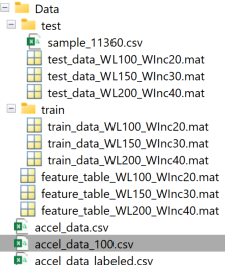

#### Raw Data at a glance

*Please write MATLAB code to plot some example trials for the activities

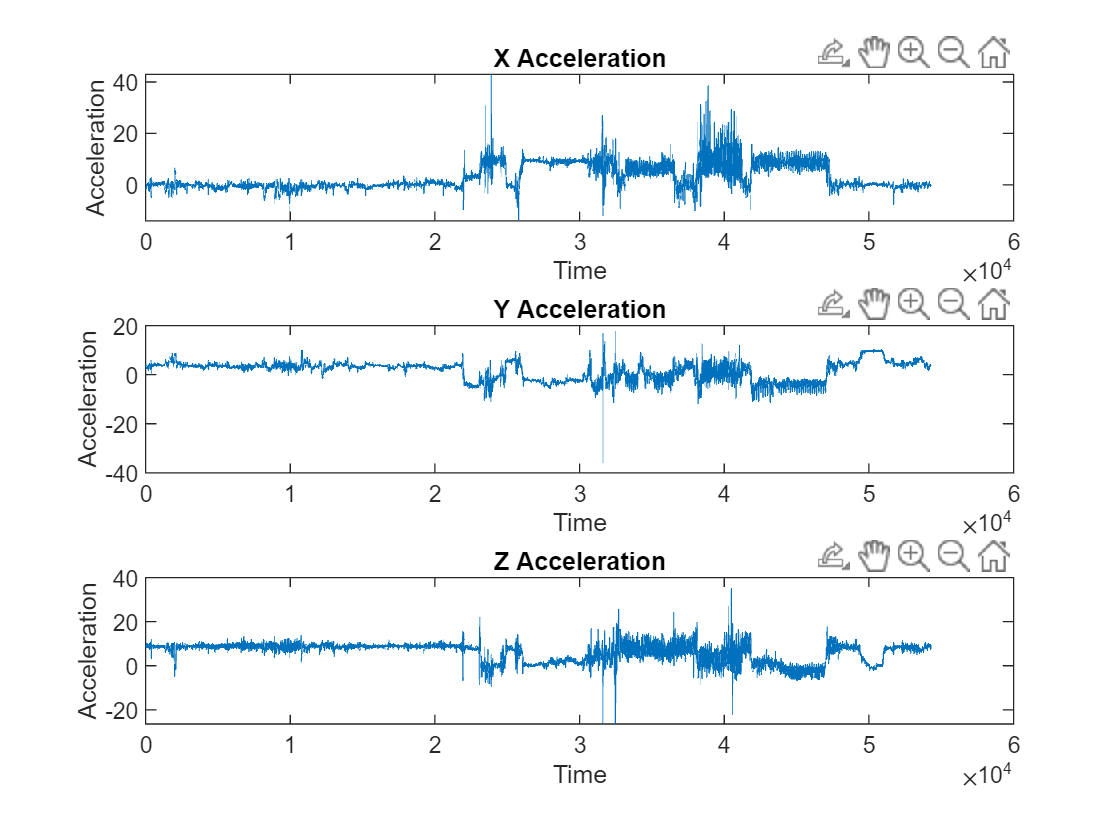

% Based on the Example, code in this section to plot the raw data that was collected
% Load the acceleration data
data = readmatrix('Data\accel_data.csv');

% Assuming the data contains x, y, and z acceleration in three columns
x_accel = data(:, 1);
y_accel = data(:, 2);
z_accel = data(:, 3);

% Plot the x, y, and z acceleration data
figure;

% Plot x acceleration
subplot(3, 1, 1);
plot(x_accel);
title('X Acceleration');
xlabel('Time');
ylabel('Acceleration');

% Plot y acceleration
subplot(3, 1, 2);
plot(y_accel);
title('Y Acceleration');
xlabel('Time');
ylabel('Acceleration');

% Plot z acceleration
subplot(3, 1, 3);
plot(z_accel);
title('Z Acceleration');
xlabel('Time');
ylabel('Acceleration');

% Load raw data from a file
data = load('Data\accel_data.csv'); % Replace 'raw_data.mat' with your file name

% Display the raw data
disp(data);

   -1.7071    3.4644    8.7891
   -1.6328    3.5602    8.8370
   -1.4126    3.6152    8.8969
   -1.3048    3.5961    8.8585
   -1.2258    3.7469    9.0118
   -1.2378    3.7158    9.0597
   -0.9385    3.5817    8.8969
   -0.8906    3.6200    8.7317
   -0.7566    3.7278    8.6526
   -0.6393    4.0127    8.4204
   -1.1301    4.1156    8.3941
   -0.7422    3.9624    8.2959
   -0.9768    3.9073    8.4563
   -1.0271    3.7421    8.5281
   -1.1636    3.7685    8.6598
   -1.3791    3.7421    8.8969
   -1.4748    3.6344    8.9783
   -1.4317    3.5889    9.0357
   -1.2450    3.6392    8.9830
   -1.1229    3.7852    8.9807
   -0.9122    3.7828    8.7891
   -0.8643    3.8116    8.6622
   -1.0391    3.8283    8.5569
   -1.0941    3.7397    8.5473
   -1.0439    3.6559    8.4803
   -0.9002    3.5362    8.4994
   -0.9960    3.5362    8.6024
   -1.0056    3.4979    8.5760
   -0.9960    3.4357    8.6143
   -1.1061    3.4165    8.4755
   -1.0654    3.3639    8.3917
   -1.0726    3.3830    8.4060
   -1.13

*Please add the screenshots of the plotted images (because the instructor will not have time to run all the code segments manually to see the results) below. Don't forget to describe the images using labels, captions, or descriptions.

...

## Feature Extraction

*Please write MATLAB code to extract **at least three** features from the raw data. Please describe how the feature extraction is done, including (*please put your answer under each question; images can also be added if needed*)

- Is the raw data segmented by analysis windows? If so, what are the window length (WL) and window increament (WInc), respectively? You have to try **at least three** different combinations of WL and WInc values and please list the values you have tried. You can also write a program to automatically use a range of WL and WInc values for feature extraction.

**Answer**

- **Window Length (WL) = 200**

- **Window Increment (WInc) = 20**

**Three different combinations of WL and WInc values:**

- **Combination 1: WL = 100, WInc = 20 (as defined in the script)**

- **Combination 2: WL = 150, WInc = 30**

- **Combination 3: WL = 200, WInc = 40**

- Which features are extracted and how are they calculated? For each feature, please write down the feature name, formula to calculate the feature, and the MATLAB code to implement the feature calculation. 

- **Mean of accelerometer data for each axis (X, Y, Z) Feature name: Mean Formula: Mean = (Sum of data points) / Number of data points**

- Please write MATLAB code to do feature extraction for both training dataset and testing dataset. For each dataset, the output from this module should be three variables: 

%X_axis_mean = mean(window_x);
%Y_axis_mean = mean(window_y);
%Z_axis_mean = mean(window_z);

- a *M x N* feature matrix, where N is the number of analysis windows; M is the number of features extracted from each window. For example, if the acceleration data has three axes X, Y, and Z, and four features are extracted from each axis, then the value of M should be three (axes) times four (features), which is 12.

- a *1 x N* label vector, where N is the number of analysis windows. This vector contains the class label (i.e. index value of the activity) for each window

- a *(M+1) x N *matrix that combines the feature matrix and the label vector, which is the requried input format for the ***Classification Learner*** app. The first M rows are feature and the last row should be the class label. 

*Please put the MATLAB code in the box below (you can create addtional .m scripts or helper functions if needed):

**Below code converts the csv data to mat with label data and window length will need to be changed I changed it to 100,150 and, 200, window increment will need to be changed I changed it to 20,30, and 40**

%% Simple feature extraction
% Data collected from smartphone accelerometer 
% Below code converts the csv data to mat with label data and windows
% lenght will need to be changed I changed it to 100, 150, 200 and window
% increment will need to be changed I changed i to 20, 30 and 40.

% Load accelerometer data
data = readmatrix('Data\accel_data.csv');

% Extract accelerometer data for each axis
accel_x = data(:, 1);
accel_y = data(:, 2);
accel_z = data(:, 3);

% Define window length (WL) and window increment (WInc)
WL = 200; % window length will need to be changed I changed it to 100 150 and 200
WInc = 40;  % window increment will need to be changed I changed it to 20 30 40

% Initialize variables for feature matrices
num_windows = floor((size(data, 1) - WL) / WInc);
X_axis = zeros(num_windows, 1);
Y_axis = zeros(num_windows, 1);
Z_axis = zeros(num_windows, 1);

% Perform feature extraction for each window
start_idx = 1;
end_idx = WL;
for i = 1:num_windows
    % Extract windowed data for each axis
    window_x = accel_x(start_idx:end_idx);
    window_y = accel_y(start_idx:end_idx);
    window_z = accel_z(start_idx:end_idx);
    
    % Calculate mean for each axis
    X_axis(i) = mean(window_x);
    Y_axis(i) = mean(window_y);
    Z_axis(i) = mean(window_z);
    
    % Update indices for next window
    start_idx = start_idx + WInc;
    end_idx = end_idx + WInc;
end

% Define labels for each movement class
walking_label = repmat({'Walking'}, num_windows/4, 1);       % Movement class 1 (Walking)
running_label = repmat({'Running'}, num_windows/4, 1);       % Movement class 2 (Running)
dancing_label = repmat({'Dancing'}, num_windows/4, 1);       % Movement class 3 (Dancing)
standing_label = repmat({'Standing'}, num_windows/4, 1);     % Movement class 4 (Standing)
labels = vertcat(walking_label, running_label, dancing_label, standing_label); % Estimated class labels for features

% Combine features and labels into a table
feature_table = table(X_axis, Y_axis, Z_axis, labels);

% Define the folder to save the feature table
output_folder = 'Data';

% Create the folder if it doesn't exist
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% Save the feature table with WL and WInc in the filename
output_filename = sprintf('%s/feature_table_WL%d_WInc%d.mat', output_folder, WL, WInc);
save(output_filename, 'feature_table');

**Below is to split the data for train and test data set**

% Split Data to Test and Train from 3 separate feature_table_WL%d_WInc%d.mat
% WL100,WInc 20 | WL150,WInc 30 | WL200, WInc40 |
% Define paths
data_path = 'Data';
train_folder = fullfile(data_path, 'train');
test_folder = fullfile(data_path, 'test');

% Create train and test folders if they don't exist
if ~exist(train_folder, 'dir')
    mkdir(train_folder);
end
if ~exist(test_folder, 'dir')
    mkdir(test_folder);
end

% Define the ratio of data for training  (70%  to 30% test split)
train_ratio = 0.7;

% Define feature table files with corresponding names
feature_files = {'feature_table_WL100_WInc20.mat', 'feature_table_WL150_WInc30.mat', 'feature_table_WL200_WInc40.mat'};
file_names = {'WL100_WInc20', 'WL150_WInc30', 'WL200_WInc40'};

for i = 1:length(feature_files)
    % Load feature table
    load(fullfile(data_path, feature_files{i}));

    % Shuffle the data to ensure randomness
    shuffled_data = feature_table(randperm(size(feature_table, 1)), :);

    % Determine the number of samples for training and testing
    num_samples = size(shuffled_data, 1);
    num_train_samples = round(train_ratio * num_samples);

    % Split the data into training and testing sets
    train_data = shuffled_data(1:num_train_samples, :);
    test_data = shuffled_data(num_train_samples+1:end, :);

    % Save training and testing data with corresponding names
    train_file_name = fullfile(train_folder, ['train_data_' file_names{i} '.mat']);
    test_file_name = fullfile(test_folder, ['test_data_' file_names{i} '.mat']);

    save(train_file_name, 'train_data');
    save(test_file_name, 'test_data');
end

% To display the table completed
disp(feature_table);

      X_axis       Y_axis        Z_axis         labels   
    __________    _________    __________    ____________

      -0.31341       3.1076        9.0405    {'Walking' }
      -0.34746       3.1234        9.0307    {'Walking' }
       -0.5391       3.3785        8.8811    {'Walking' }
      -0.62115       3.4299         8.859    {'Walking' }
      -0.52336       3.4982        8.8402    {'Walking' }
      -0.63862       3.6875        8.6868    {'Walking' }
      -0.20008       3.5813        8.7743    {'Walking' }
        0.1955       3.4949        8.8478    {'Walking' }
       0.38199        3.519        8.8389    {'Walking' }
       0.32608       3.6007         8.789    {'Walking' }
       0.42082       3.5967        8.8827    {'Walking' }
        0.3114       3.7922        8.7807    {'Walking' }
       0.30335       3.9566        8.6815    {'Walk

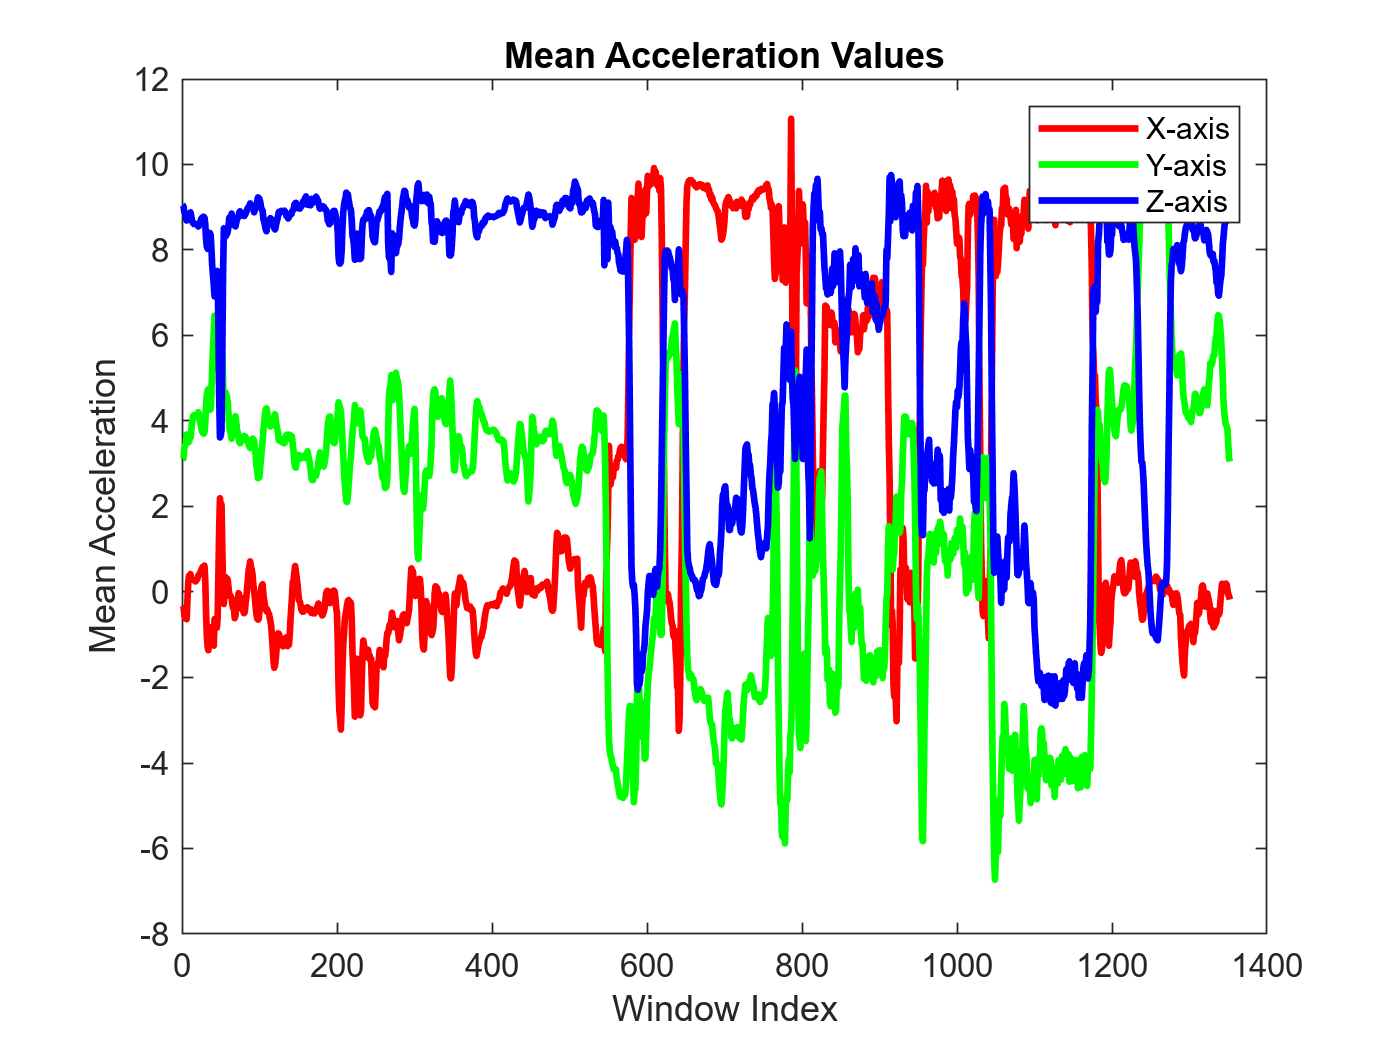

figure;
plot(X_axis, 'r', 'LineWidth', 2);
hold on;
plot(Y_axis, 'g', 'LineWidth', 2);
plot(Z_axis, 'b', 'LineWidth', 2);
xlabel('Window Index');
ylabel('Mean Acceleration');
legend('X-axis', 'Y-axis', 'Z-axis');
title('Mean Acceleration Values')

*Please add the screenshots of the generated results (e.g. generated variables in the workspace, content of the feature matrix, image of the plotted feature values) of this section (because the instructor will not have time to run all the code segments manually to see the results) below. **Don't forget to explain the results**.

- **First  screenshot captures the variables created after extracting features. These variables include X-axis, Y-axis, Z-axis, and labels.**

- **Second  screenshot shows the contents of the feature matrix named "feature_table". It contains the average acceleration values for each axis (X, Y, and Z) along with their corresponding activity labels.  **

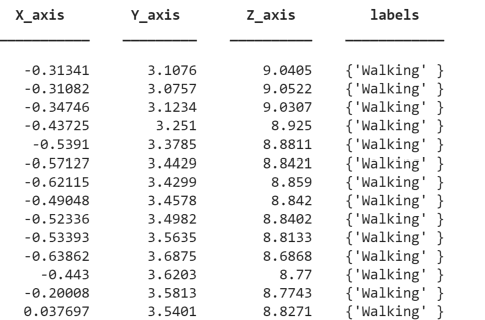

- **Last  screenshot visualizes the average acceleration values for each axis (X, Y, and Z) throughout the analysis windows. The legend clarifies which color corresponds to each axis.**

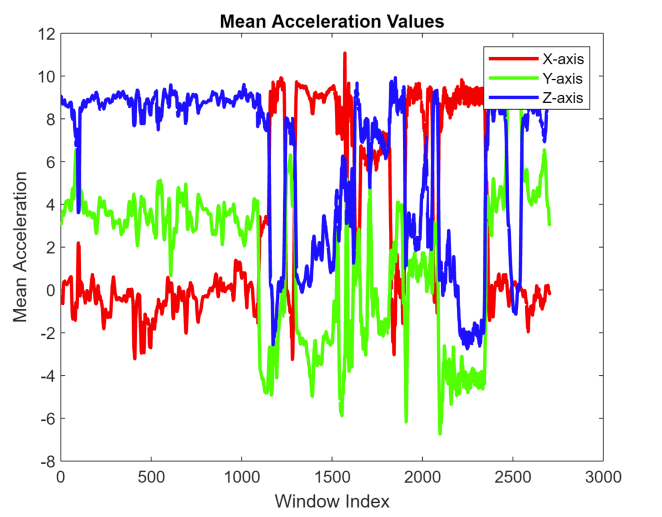

...

## Classification - Train a Model

Now we can train a classifier model using the feature matrix generated in the previous step. In this assignment, we use the MATLAB built-in ***Classification Learner*** app to do pattern classification. 

You can launch the ***Classification Learner*** app by running the code below or open it from the APPS menu. Please refer to the references provided at the top of this document to learn how to use the app.

classificationLearner

The Classification Learner requires an input combining the feature variables and the class labels, which should be the third variable generated from your feature extraction code for the training dataset. In this assignment, you are required to conduct several experiments to train classifiers with different combinations of parameters and test them on the testing dataset. You need to try at least three different combinations of WL and WInc values, adding feature normalization/standization or not, adding feature reduction technique (e.g. PCA) or not, and at least two different classification methods. Rembmer, you can only change one parameter at a time, so the combinations could be a lot. 

*You need to report the results in a table using the following suggested format (you can create the table using other software and add the table image here):

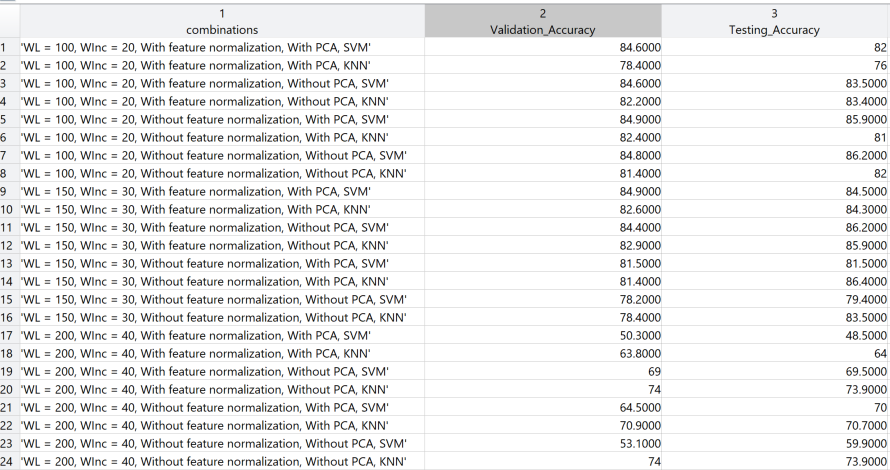

*You need to then conclude which parameters yield the best results. 

*In addition,  you need to include the screenshots of your experiemntal procedure of this section (e.g. generated variables in the workspace, screenshot of the ClassifiationLearner app configuration for representative experimental trials) to demonstrate you have done the work by yourself. **Don't forget to explain the screenshots**.

**Explanation** 

**For this experiment, I conducted a series of trials using the ClassificationLearner app to train and test classification models on accelerometer data. The aim was to explore various combinations of window length (WL), window increment (WInc), feature normalization, principal component analysis (PCA), and different classification algorithms such as Support Vector Machine (SVM) and k-Nearest Neighbors (KNN). Below are the configurations and models trained for each combination **

- **Description: This model utilizes a window length of 100 with a window increment of 20. Features are normalized, and PCA is applied for dimensionality reduction before training with the SVM algorithm.**

- **Screenshot: **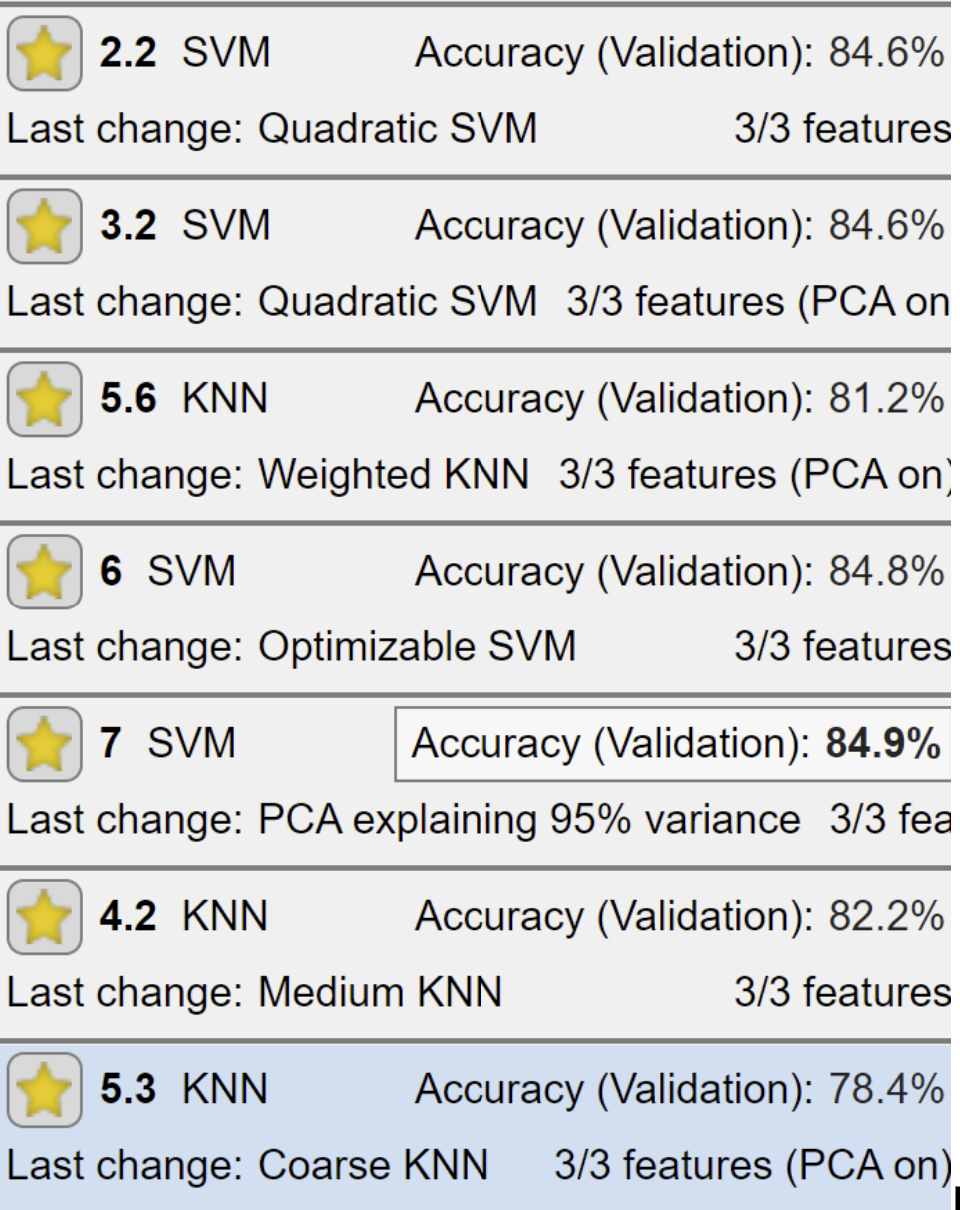

- **Description: Similar to the first model, this configuration includes feature normalization and PCA, but utilizes the KNN algorithm for classification.**

- **Screenshot: **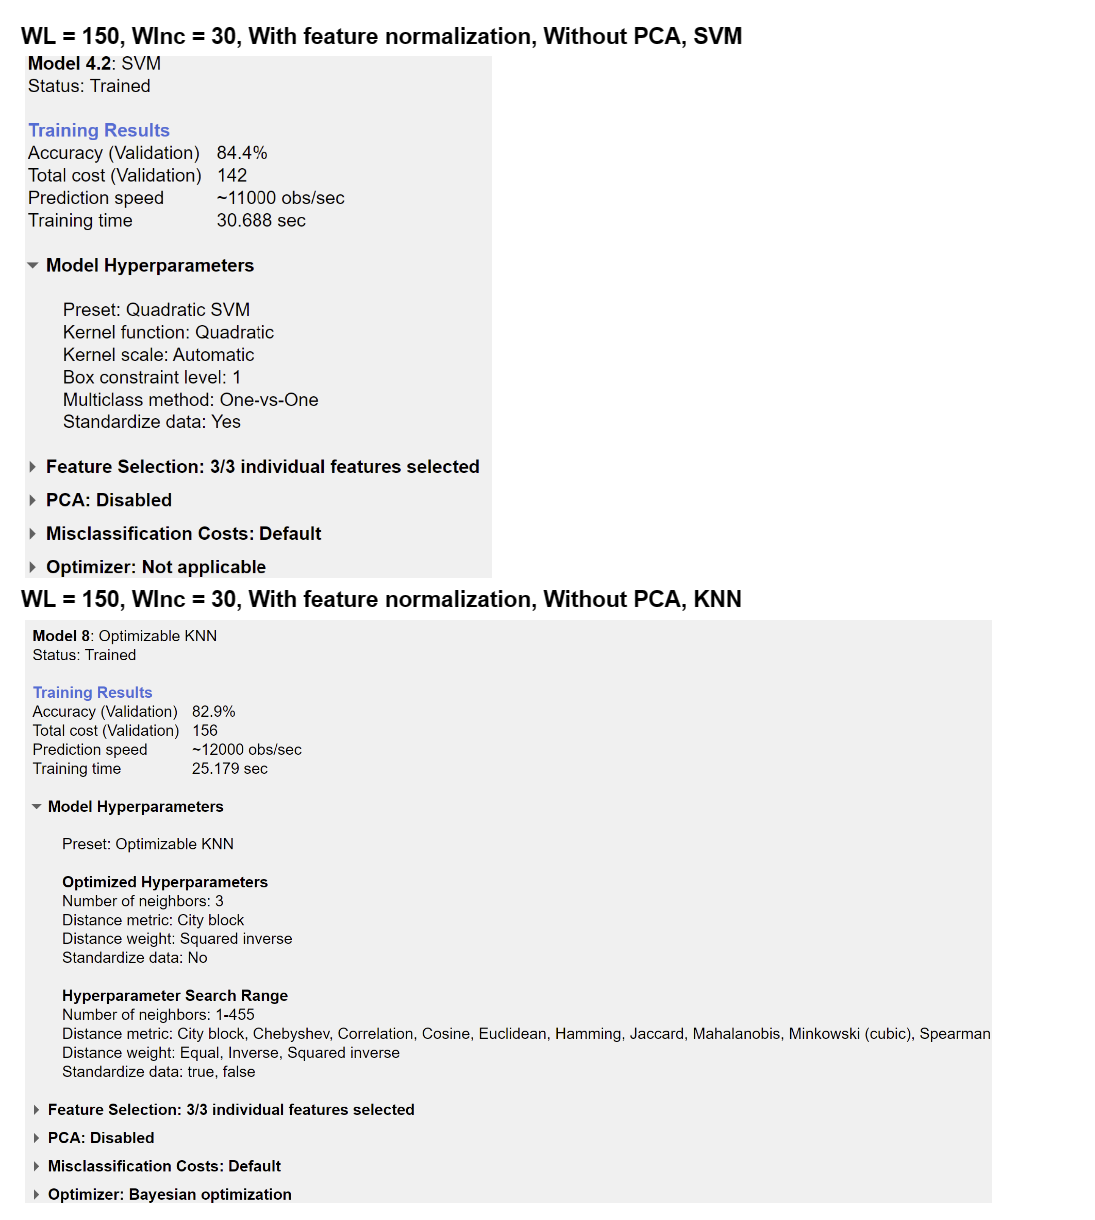

- **Description: This model employs a window length of 150 and a window increment of 30. Features are not normalized, and PCA is not applied. The classification is performed using the KNN algorithm.**

- **Screenshot: **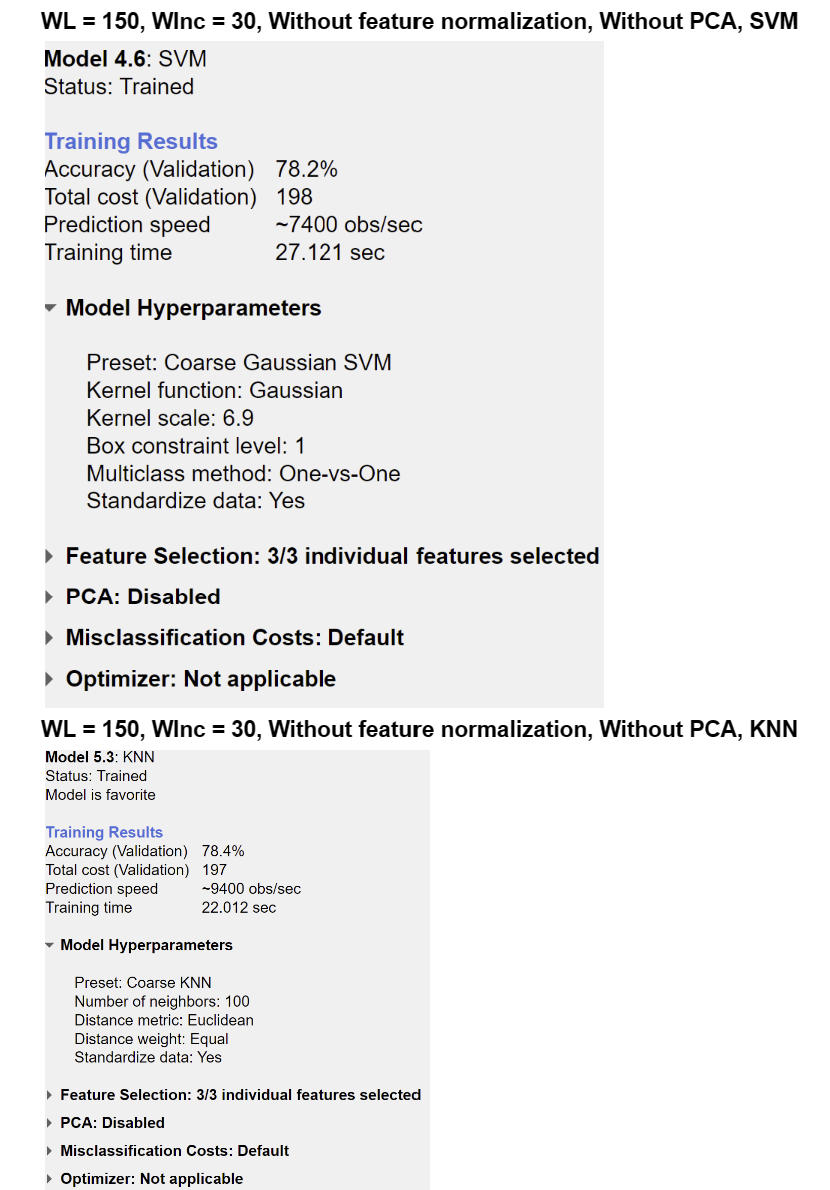

- **Description: This Model involves a window length (WL) of 200 data points and a window increment (WInc) of 40 data points.Feature normalization is applied to standardize the features. Principal Component Analysis (PCA) is used for feature reduction. Support Vector Machine (SVM) is the chosen classifier.**

- **Screenshot **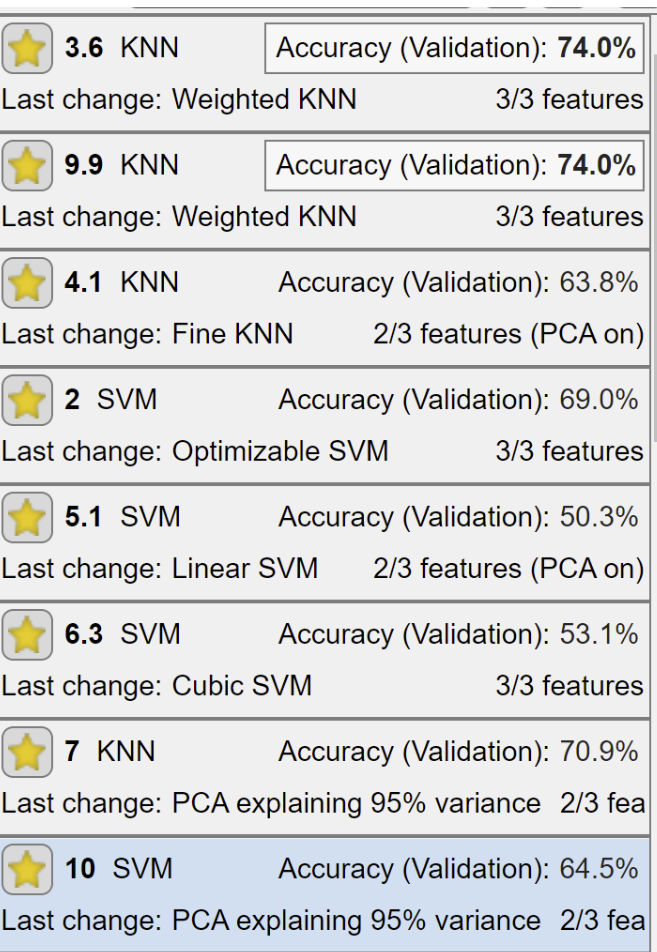

## Analyze the Extracted Features

- **mean_acceleration**

- **std_acceleration**

- **peak_acceleration**

**Below are the **

- **Store mean acceleration for each axis**

- **Store standard deviation for each axis**

- **Store peak acceleration for each axis**

% Load accelerometer data from a CSV file
data = readmatrix('Data\accel_data.csv');

% Assuming the data contains x, y, and z acceleration in three columns
x_accel = data(:, 1);
y_accel = data(:, 2);
z_accel = data(:, 3);

% Define window parameters
window_length = 100; % Number of data points in each window
window_increment = 20; % Increment for moving the window

% Initialize arrays to store extracted features
num_windows = floor((size(data, 1) - window_length) / window_increment);
mean_acceleration = zeros(num_windows, 3); % Store mean acceleration for each axis
std_acceleration = zeros(num_windows, 3); % Store standard deviation for each axis
peak_acceleration = zeros(num_windows, 3); % Store peak acceleration for each axis

% Extract features for each window
for i = 1:num_windows
    % Extract windowed data for each axis
    window_x = x_accel((i-1)*window_increment + 1 : (i-1)*window_increment + window_length);
    window_y = y_accel((i-1)*window_increment + 1 : (i-1)*window_increment + window_length);
    window_z = z_accel((i-1)*window_increment + 1 : (i-1)*window_increment + window_length);

    % Calculate mean, standard deviation, and peak for each axis
    mean_acceleration(i, :) = mean([window_x, window_y, window_z]);
    std_acceleration(i, :) = std([window_x, window_y, window_z]);
    peak_acceleration(i, :) = max([window_x, window_y, window_z]);
end

   -0.8117    3.1776    9.0412
   -0.5288    3.0755    9.0651
   -0.3263    2.9934    9.1265
   -0.1098    2.9979    9.0815
    0.0677    3.0263    9.0921
    0.1849    3.0376    9.0398
   -0.0929    3.0760    9.0393
   -0.3686    3.2534    8.9350
   -0.7647    3.5041    8.7684
   -1.1459    3.7308    8.6700
   -1.3274    3.8482    8.6444
   -1.1494    3.7839    8.6786
   -0.6123    3.6622    8.7490
   -0.2820    3.4923    8.9120
    0.0781    3.3962    8.9566
    0.0502    3.5268    8.7293
    0.2634    3.4568    8.8614
    0.2122    3.5004    8.7995
    0.3574    3.5879    8.7423
    0.3129    3.5936    8.7389
    0.5952    3.4353    8.9741
    0.5006    3.5812    8.8163
    0.3003    3.5806    8.8758
    0.2948    3.6134    8.8356
    0.2867    3.7028    8.7966
    0.2464    3.7580    8.7912
    0.2306    3.8609    8.7510
    0.3225    4.0037    8.6857
    0.2687    4.1533    8.6012
    0.3200    4.2103    8.5665
    0.3262    4.2840    8.5174
    0.3228    4.2970    8.5205
    0.28

    0.4032    0.4442    0.4299
    0.5365    0.3529    0.4158
    0.5133    0.2832    0.3722
    0.4530    0.2360    0.3267
    0.4690    0.2028    0.3231
    0.3848    0.2440    0.2918
    0.6845    0.2904    0.3029
    0.8479    0.4557    0.3405
    0.9541    0.4893    0.4216
    0.7939    0.4550    0.5004
    0.6271    0.3810    0.5122
    0.8694    0.4909    0.5603
    1.3992    0.5293    0.5950
    1.3074    0.5621    0.6256
    1.2993    0.5056    0.5860
    1.5050    0.6783    1.1441
    1.5016    0.8294    1.2619
    1.3753    0.8209    1.2728
    1.3502    0.7703    1.2244
    1.2030    0.7547    1.1902
    0.6098    0.5679    0.6330
    0.4427    0.1682    0.3116
    0.3478    0.1323    0.1793
    0.2529    0.1955    0.2787
    0.2768    0.2914    0.3182
    0.2752    0.2920    0.3172
    0.2712    0.2569    0.3162
    0.2893    0.2620    0.3166
    0.2925    0.2988    0.3108
    0.2691    0.2976    0.2963
    0.3137    0.2613    0.2768
    0.3323    0.2636    0.2985
    0.31

% Display for further analyze the extracted features

    0.1580    4.1156   10.2999
    0.6081    3.8666   10.2999
    0.6081    3.8666   10.2999
    0.6081    3.8666   10.2999
    0.9194    3.8666   10.2999
    1.0008    3.6248    9.4954
    1.0008    3.8451    9.4954
    1.0008    4.2641    9.4954
    1.0008    4.4077    9.4954
    1.0008    4.6136   10.0892
    0.1149    4.6136   10.0892
    1.8292    4.6136   10.2280
    2.5211    4.6136   10.2280
    2.5211    4.6136   10.6590
    2.5211    4.4604   10.6590
    2.5211    5.8897   11.7460
    2.9329    5.8897   11.7460
    2.9329    5.8897   11.7460
    2.9329    5.8897   11.7460
    2.9329    5.8897   11.7460
    2.9329    3.9863   11.4156
    1.5203    3.9863    9.6343
    1.5203    3.9097    9.2273
    0.9553    4.1922    9.4451
    0.9553    4.6902    9.4451
    0.9553    4.6902    9.4451
    0.9553    4.6902    9.4451
    0.9553    4.9249    9.4451
    0.8308    4.9249    9.2871
    0.9313    4.9249    9.1147
    0.9313    4.9249    9.1147
    0.9313    4.9249    9.1722
    0.93

start_idx = 54081

disp(mean_acceleration);
disp(std_acceleration);
disp(peak_acceleration);